# **垂直跳び　跳躍高**

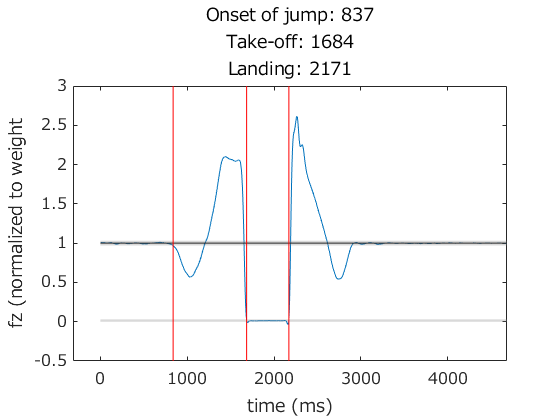

clear
close all
clc


% *** サンプルデータ を load ***
fileName = 'DemoDataSJ' ;
load(fileName) ;

% *** 実験実習で測定計測したデータ を load***
fileName = 'Data_S08' ; % ←　被験者番号を指定する
load(fileName) ;

Data = DataStruct.CMJ(1) ; % ←　条件名・試行番号を指定する
grfs = Data.Forces ;
Markers = Data.Markers ;
% ****


%%
% fz
fz = grfs(:,3) + grfs(:,6) ;

% イベント検出
Prm.Alpha = 0.03 ;
Prm.Beta = 0.03 ;
Prm.Win = 50 ;

JumpEvent = detectJumpEvent(fz, Prm) ;
figJumpEvent(fz, Prm, JumpEvent) ;

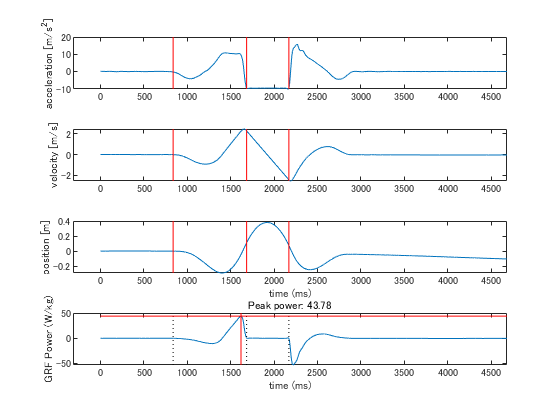


% 床反力パワー
[GRFPower, PowerTimeSeries] = calculatePower(fz, JumpEvent) ;
figGRFPower(GRFPower, PowerTimeSeries, JumpEvent) ;

# **跳躍高の分析**

いくつかの方法で、ジャンプ高を分析してみましょう

・マーカーから計算した重心位置　→　最大値

・加速度を2回積分　→　最大値

・床反力から分析した滞空時間　→　ジャンプ高

・床反力がした仕事　→　離地時の運動エネルギー

どうしてこれらは一致しないのでしょうか。

プログラミングコードを読んで、何を計算しているのかを把握した上で、考えてください


% マーカーから計算した重心位置　→　最大値と測定終了時の差
jumpHeight1 = max(Markers.Gt(:,3)) - mean(Markers.Gt(end-1000:end,3)) ; % (mm)
jumpHeight1 = jumpHeight1 / 1000

jumpHeight1 = 0.4137


% 加速度を2回積分　→　最大値と着地時の差
jumpHeight2 = max(PowerTimeSeries.Z) - PowerTimeSeries.Z(JumpEvent.Landing)

jumpHeight2 = 0.3052


% 離地時の速度　→　跳躍高
velAtTakeOff = PowerTimeSeries.Vel(JumpEvent.TakeOff) ;
jumpHeight3 = (1/2) * velAtTakeOff^2 / gravity

jumpHeight3 = 0.2676


% 床反力がした仕事　→　離地時の運動エネルギー
grfPower = PowerTimeSeries.GRFPower ; % power (W) / bodyMass (kg)
gravityPower = gravity*PowerTimeSeries.Vel ; % 重力がした仕事
netPower = grfPower - gravityPower ; % 身体がされた仕事
keAtTakeOff = sum(netPower(JumpEvent.OnsetJump:JumpEvent.TakeOff)) * 0.001 ; % 1/2 mv^2 / bodyMass
jumpHeight4 = keAtTakeOff / gravity

jumpHeight4 = 0.2664


% 床反力から分析した滞空時間　→　ジャンプ高
flightTime = (JumpEvent.Landing - JumpEvent.TakeOff) / 1000 ; % (s)
velAtTakeOff = gravity * (flightTime/2) ;
jumpHeight5 = (1/2) * velAtTakeOff^2 / gravity

jumpHeight5 = 0.2907

function JumpEvent = detectJumpEvent(fz, Prm)
    
    % パラメータ
    alpha = Prm.Alpha ;
    beta = Prm.Beta ;
    win = Prm.Win ;
    
    % イベント検出に共通しても用いる変数
    n = length(fz) ;
    baseFz = mean(fz(1:1000)) ; % 最初の1秒の平均値をベースラインとする　
                                %　なので、測定開始後1秒は静止していなければならない
    baseFz = 1 ;

    tOnsetJump = 0 ; % 変数の初期化
    for ii = 2:n-win
        % 条件１　ジャンプ開始時刻の直前の fz は、ベースライン±αの範囲内にある
        criteria1 = fz(ii-1) < baseFz*(1+alpha) && fz(ii-1) > baseFz*(1-alpha) ;
    
        % 条件２　ジャンプ開始時刻から win (ms)間、 fz は、ベースライン±α の範囲外にある
        criteria2 = all(fz(ii:ii+win) >= baseFz*(1+alpha)) || all(fz(ii:ii+win) <= baseFz*(1-alpha)) ;
    
        if criteria1 && criteria2 % 上記の2条件を同時に満たす
            tOnsetJump = ii ;
            break % 1回検出したら、ループを抜ける
        end
        
    end
    
    
    % takeoff
    tTakeOff = 0 ;
    for ii = 2:n-win
        if all( fz(ii:ii+win) < beta )
            tTakeOff = ii ;
            break
        end
    end
    
    % landing
    tLanding = 0 ;
    for ii = tTakeOff:n-win
        if all( fz(ii:ii+win) > beta )
            tLanding = ii ;
            break
        end
    end
    
    % output
    JumpEvent.OnsetJump = tOnsetJump ;
    JumpEvent.TakeOff = tTakeOff ;
    JumpEvent.Landing = tLanding ;
    
end


function figJumpEvent(fz, Prm, JumpEvent)
    
    % パラメータ
    alpha = Prm.Alpha ;
    beta = Prm.Beta ;
    win = Prm.Win ;
    
    % イベント検出に共通しても用いる変数
    n = length(fz) ;
    baseFz = mean(fz(1:1000)) ; % 最初の1秒の平均値をベースラインとする　
                                %　なので、測定開始後1秒は静止していなければならない
    baseFz = 1 ;
    
    % イベント時刻
    tOnsetJump = JumpEvent.OnsetJump ;
    tTakeOff = JumpEvent.TakeOff ;
    tLanding = JumpEvent.Landing ;
    
    % 図の作成
    figure
    plot(fz) ; % イベント検出に用いた時系列データ 
    
    % イベント検出に用いた閾値を図示　（※　進矢の自作関数を使っています
    lineplot(1, 'h', 'k') ; 
    arealine([baseFz-alpha, baseFz+alpha], 'h') ; 
    arealine([0, beta], 'h') ;
    
    % 検出されたイベントを図示
    lineplot([tOnsetJump, tTakeOff, tLanding], 'v', 'r') ;
    
    % 表示範囲を設定
    xlim = [-2000,3000] ;
    set(gca, 'xlim', xlim+tTakeOff)
    
    % 凡例等
    xlabel('time (ms)')
    ylabel('fz (normalized to weight')
    titleText = { sprintf('Onset of jump: %d', tOnsetJump) ;... % sprintf: 数値を文字列にフォーマットするときに用いる
                  sprintf('Take-off: %d', tTakeOff) ;...
                  sprintf('Landing: %d', tLanding) } ;
    title(titleText)
    set(gca, 'fontname', 'meiryo', 'fontsize', 12)

end


function [GRFPower, PowerTimeSeries] = calculatePower(fz, JumpEvent)
    
%     fz = fz / mean(fz(1:1000)) ;
    
    % 数値積分
    z2Dot = (fz-1) * gravity ; % ここの fz が、体重で正規化された値であることに注意
    zDot = cumtrapz(z2Dot) * 0.001 ; % cumtrapz: 累積台形積分を計算する関数
    z = cumtrapz(zDot) * 0.001 ;
    z = z - z(JumpEvent.OnsetJump) ; % onset of jump motion の時刻における位置を基準とする
    
    PowerTimeSeries.Acc = z2Dot ;
    PowerTimeSeries.Vel = zDot ;
    PowerTimeSeries.Z = z ;
        
    % power
    grfPower = (fz*gravity) .* zDot ; % [N/bodyMass * m/s] = [J/s /bodyMass] = [W/bodyMass]
    PowerTimeSeries.GRFPower = grfPower ;
    
    avgPower = mean(grfPower(JumpEvent.OnsetJump:JumpEvent.TakeOff)) ; % 動作開始から離地までの平均パワー
    [peakPower, tPeakPower] = max(grfPower(JumpEvent.OnsetJump:JumpEvent.TakeOff)) ; % [W / kg] ### weight = m [kg] * g [m/s2]
    tPeakPower = tPeakPower + JumpEvent.OnsetJump - 1 ;
    
    GRFPower.AvgPower = avgPower ;
    GRFPower.PeakPower = peakPower ;
    GRFPower.tPeakPower = tPeakPower ;
    
    
end


function figGRFPower(GRFPower, PowerTimeSeries, JumpEvent)
    xlim = [-2000,3000] ;
    
    figure
    subplot(4,1,1) ;
    plot(PowerTimeSeries.Acc)
    ylabel('acceleration [m/s^2]')
    lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'r') ;
    set(gca, 'xlim', xlim + JumpEvent.TakeOff) ;
    
    subplot(4,1,2) ;
    plot(PowerTimeSeries.Vel)
    ylabel('velocity [m/s]')
    lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'r') ;
    set(gca, 'xlim', xlim + JumpEvent.TakeOff) ;
    
    subplot(4,1,3) ;
    plot(PowerTimeSeries.Z)
    ylabel('position [m]')
    lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'r') ;
    set(gca, 'xlim', xlim + JumpEvent.TakeOff) ;
    xlabel('time (ms)')
    
    subplot(4,1,4) ;
    plot(PowerTimeSeries.GRFPower) ;
    lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'k:') ;
    lineplot(GRFPower.tPeakPower, 'v', 'r') ;
    lineplot(GRFPower.PeakPower, 'h', 'r') ;
    set(gca, 'xlim', xlim + JumpEvent.TakeOff) ;
    ylabel('GRF Power (W/kg)')
    xlabel('time (ms)')
    title(sprintf('Peak power: %0.2f', GRFPower.PeakPower))



end

